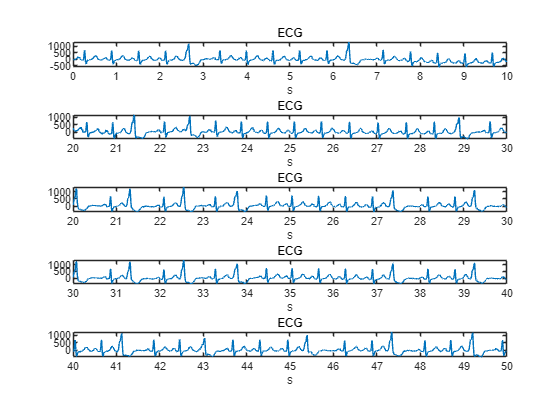

%% Load data and visualize
addpath("routines\");

load("data/ecgpvc.mat");
visualpvc(ecgpvc);

## Take five representative ectopic beats

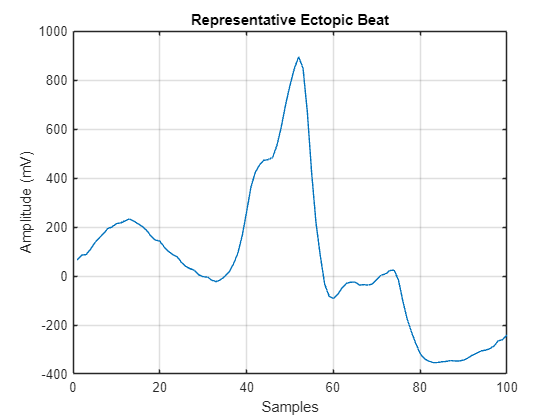

% Manually take the peaks
peaks = [39.25, 41.12, 45.39,47.345 ,49.1 ];
peak_samples = peaks * 200;
sample_window = 50;

window_accum_values = zeros(sample_window*2, 1);
for i = peak_samples
    window = ecgpvc(i-sample_window:i+sample_window-1);
    window_accum_values = window_accum_values + window;
end

representative_beat = window_accum_values / length(peak_samples);

figure;
plot(representative_beat);
title('Representative Ectopic Beat');
xlabel('Samples')
ylabel('Amplitude (mV)')
grid on;

## Xcorr between ECG signal and Representative ectopic Beat

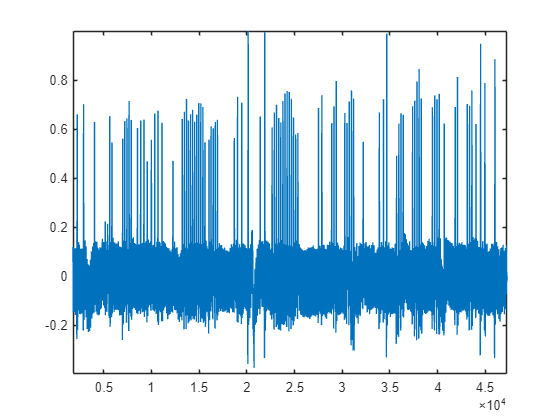

% Normalize signals

[corr, lags] = xcorr(ecgpvc, representative_beat);
trimmed_corr = corr(lags >= 0);

% Normalize corr
normalized_trim_corr = trimmed_corr / max(trimmed_corr);

figure()
plot(normalized_trim_corr);

## Apply threshold

threshold = 0.9;

ecb_idxs = find(normalized_trim_corr >= threshold);